# Current in a Wire Loop

% Light speed
lightSpeed=physconst('LightSpeed');


## The Electric force between two electrons

eo = 8.8541878188e-12;
mo = 4*pi()*1.0e-7;
Ke=1.0/(4*pi()*eo) % Electric constant

Ke = 8.9876e+09

QCharge = 1.602176634e-19 % Charge of proton columbs

QCharge = 1.6022e-19

oneApereElectrons = 1.0/QCharge

oneApereElectrons = 6.2415e+18

% Electric force beween two proton charges at 1 meter
EF = Ke*QCharge*QCharge;

% The force constant between two electrons in photons per second
Kf = lightSpeed/eo;


## Set up a wire loop with charge density

radius = 0.10; %  radius of loop
chargepos = 0.00010; % -starting to +end point in X in meters

magVel = 0.00010; % Electron drift speed inside the wire m/s
chargeVel = [100.0,0]; % the velocity vector of the charge at the x-position m/s

totalelectrons = 2*pi()*radius*oneApereElectrons; % Total moving charge in a loop

totalChargePerMeter = totalelectrons*QCharge/(2*pi()*radius) % Columbs per meter

totalChargePerMeter = 1


current = totalChargePerMeter*magVel % Amperes (Columns per meter)

current = 1.0000e-04


magForce = QCharge*sqrt(dot(chargeVel,chargeVel))*mo*current/(2*radius) % Expected force

magForce = 1.0067e-26



xgridsize = 20;
gridsize = 100000; % How many samples of the charge density
steptheta = 2*pi()/gridsize;
theta=linspace(0,2*pi()-steptheta,gridsize);

density = totalelectrons*ones(size(theta))/gridsize; % Number of electrons per sample

X=radius*cos(theta);
Y=radius*sin(theta);
samplingX = linspace(-chargepos,chargepos,xgridsize); % 

electronvelX = magVel*sin(theta);
electronvelY = -magVel*cos(theta); % meters per second of electrons moving in a metalic wire

%plot(X)
%plot(Y)
%plot(electronvelX)
%plot(electronvelY)

## Compute force of a moving negative charge

%plot(electronvelX)
%plot(electronvelY)


zerovector = zeros(size(samplingX));

forceX_e = zerovector; % Galiean X force for Electron
forceY_e = zerovector; % Galiean Y force for electron 
forceX_p = zerovector; % Galiean X force for proton
forceY_p = zerovector; % Galiean Y force for proton

EforceX_e = zerovector; % Electron X Force Adjusted for charge velocity
EforceY_e = zerovector; % Electron Y Force Adjusted for charge velocity
EforceX_p = zerovector; % Proton X Force Adjusted for charge velocity
EforceY_p = zerovector; % Proton Y Force Adjusted for charge velocity

Enetforce_x = zerovector; % The net force electron plus proton
Enetforce_y = zerovector; % The net force electron plus proton
Gnetforce_x = zerovector; % The net Galilean force electron plus proton
Gnetforce_y = zerovector; % The net Galilean force electron plus proton
timetoarrival = zerovector;

for d=1:xgridsize
    dist = samplingX(d);
    for i=1:gridsize
        pos=[X(i),Y(i)];
        ppos = pos;
        ppos(1) = ppos(1)-dist;
        edist = dot(ppos,ppos);

% Force assuming galilean relativity for the proton (not moving)
        velo=[0,0];
        [timea,vel]=ArrivalTime(pos,velo,dist,lightSpeed);
        timetoarrival(d) = timetoarrival(d) + timea;
        rvel = vel + velo;
        densAdj = sqrt(dot(rvel,rvel))/lightSpeed;
        fmag = densAdj*density(i)/edist;

        nvelp = vel/lightSpeed;
        gpforx_p = nvelp(1)*fmag;
        gpfory_p = nvelp(2)*fmag;
        forceX_p(d)=forceX_p(d) - gpforx_p;
        forceY_p(d)=forceY_p(d) - gpfory_p;

% Electrostatic Force ajusted for Relative speed 
        rvel = rvel - chargeVel; 
        vrelm = sqrt(dot(rvel,rvel));
        dpv = dot(nvelp,rvel/vrelm)^2;

        csent = cross([nvelp,0],[rvel/vrelm,0]);
        sen2p = dot(csent,csent); % dvp = 1.0-sen2p


        pforx_p = gpforx_p*dpv;
        pfory_p = gpfory_p*dpv;
        EforceX_p(d)=EforceX_p(d) - pforx_p;
        EforceY_p(d)=EforceY_p(d) - pfory_p;

% Force assuming galilean relativity for the electron
        velo=[electronvelX(i),electronvelY(i)];
        [timea,vel]=ArrivalTime(pos,velo,dist,lightSpeed);
        rvel = vel + velo;
        densAdj = sqrt(dot(rvel,rvel))/lightSpeed;
        fmag = densAdj*density(i)/edist;

        nvele = vel/lightSpeed;
        gpforx_e = nvele(1)*fmag;
        gpfory_e = nvele(2)*fmag;
        forceX_e(d)=forceX_e(d)+gpforx_e;
        forceY_e(d)=forceY_e(d)+gpfory_e;

        Gnetforce_x(d) = Gnetforce_x(d) + (gpforx_e - gpforx_p);
        Gnetforce_y(d) = Gnetforce_y(d) + (gpfory_e - gpfory_p);

% Electrostatic Force ajusted for Relative speed 
        rvel = rvel - chargeVel; 
        vrelm = sqrt(dot(rvel,rvel));
        dpv = dot(nvele,rvel/vrelm)^2;
        csent = cross([nvele,0],[rvel/vrelm,0]);
        sen2e = dot(csent,csent); % dvp = 1.0-sen2p


        pforx_e = gpforx_e*dpv;
        pfory_e = gpfory_e*dpv;
        EforceX_e(d)=EforceX_e(d)+pforx_e;
        EforceY_e(d)=EforceY_e(d)+pfory_e;

%        Enetforce_x(d) = Enetforce_x(d) + (pforx_e - pforx_p);
%        Enetforce_y(d) = Enetforce_y(d) + (pfory_e - pfory_p);

        Enetforce_x(d) = Enetforce_x(d) + (gpforx_p*sen2p - gpforx_e*sen2e);
        Enetforce_y(d) = Enetforce_y(d) + (gpfory_p*sen2p - gpfory_e*sen2e);

    end
end

Enetforce_x = Enetforce_x*EF;
Enetforce_y = Enetforce_y*EF;
EforceX_e = EforceX_e*EF;
EforceY_e = EforceY_e*EF;
EforceX_p = EforceX_p*EF;
EforceY_p = EforceY_p*EF;
Gnetforce_x = Gnetforce_x*EF;
Gnetforce_y = Gnetforce_y*EF;
forceX_e = forceX_e*EF;
forceY_e = forceY_e*EF;
forceX_p = forceX_p*EF;
forceY_p = forceY_p*EF;



## The outputs

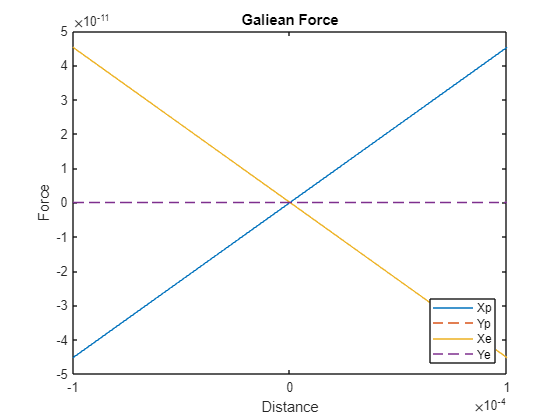

plot(samplingX,forceX_p)
title('Galiean Force');
xlabel('Distance') 
ylabel('Force') 
hold on
plot(samplingX,forceY_p,'--')
plot(samplingX,forceX_e)
plot(samplingX,forceY_e,'--')
legend({'Xp',"Yp","Xe","Ye"},'Location','southeast')
hold off

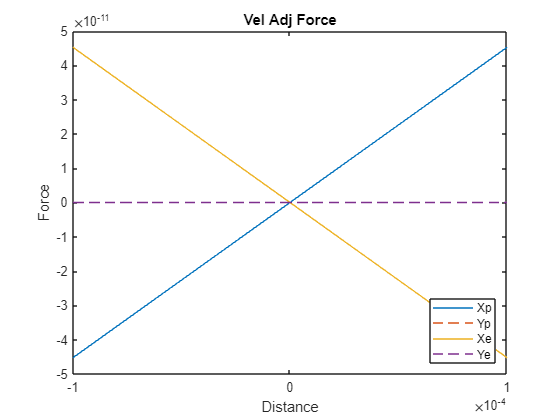


plot(samplingX,EforceX_p)
title('Vel Adj Force');
xlabel('Distance') 
ylabel('Force') 
hold on
plot(samplingX,EforceY_p,'--')
plot(samplingX,EforceX_e)
plot(samplingX,EforceY_e,'--')
legend({'Xp',"Yp","Xe","Ye"},'Location','southeast')
hold off

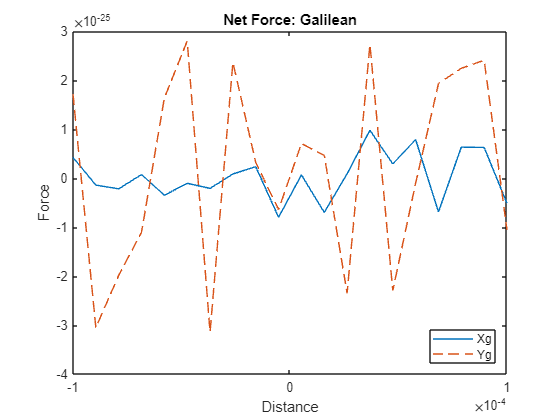


plot(samplingX,Gnetforce_x)
title('Net Force: Galilean');
xlabel('Distance') 
ylabel('Force') 
hold on
plot(samplingX,Gnetforce_y,'--')
legend({'Xg',"Yg"},'Location','southeast')
hold off

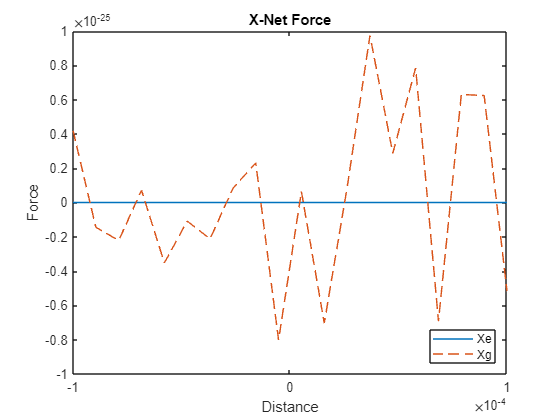


plot(samplingX,Enetforce_x)
title('X-Net Force');
xlabel('Distance') 
ylabel('Force') 
hold on
plot(samplingX,Gnetforce_x,'--')
legend({'Xe',"Xg"},'Location','southeast')
hold off

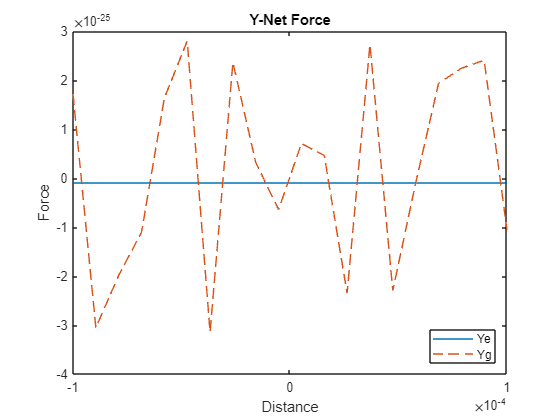


plot(samplingX,Enetforce_y)
title('Y-Net Force');
xlabel('Distance') 
ylabel('Force') 
hold on
plot(samplingX,Gnetforce_y,'--')
legend({'Ye',"Yg"},'Location','southeast')
hold off

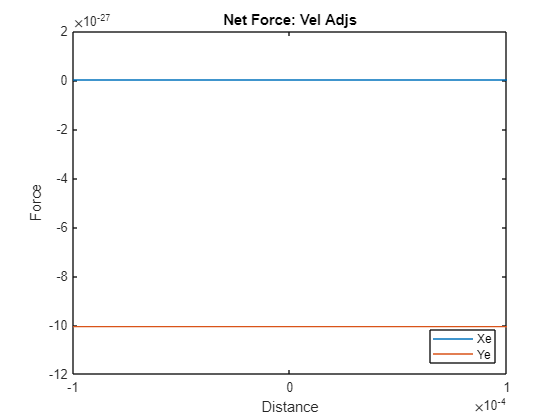



plot(samplingX,Enetforce_x)
title('Net Force: Vel Adjs');
xlabel('Distance') 
ylabel('Force') 
hold on
plot(samplingX,Enetforce_y)
legend({'Xe',"Ye"},'Location','southeast')
hold off


sqrt(mean(Enetforce_x.^2+Enetforce_y.^2))

ans = 1.0067e-26

sqrt(mean(Enetforce_x.^2+Enetforce_y.^2))/magForce

ans = 1.0000